# CWEDMR analysis for reverse bias 1V under illumination at 25K

1. Baseline correction 2. Phase correction 3. Fit of Pb0, Db-like

clearvars, close all

## Import

file0 = dir('013_1p0V_10KHz_3G_25K_10Scan_0Deg_Light.DTA');
file90 = dir('013_1p0V_10KHz_3G_25K_10Scan_90Deg_Light.DTA');
[data.BRaw, data.spc, data.Params] = eprloadQuad(file0.name, file90.name);
data.title = strrep(strrep(file0.name, '0Deg_', ''), '_', ' ');

## Field offset

Field offset(obtained from NaC60_Field_Calibration in this same folder) and conversion to mT

data.B = (data.BRaw(:) - 5.181)/10;

## Baseline and phase correction

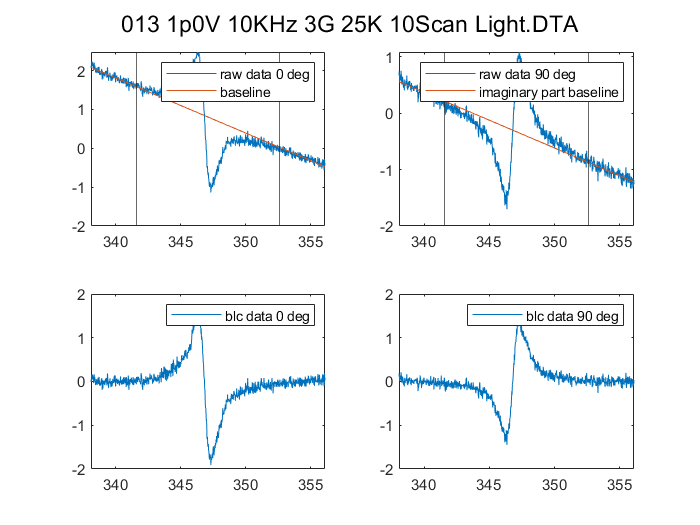

Opt.range = [1, 200];
Opt.range1 = [numel(data(1).B) - 200, numel(data(1).B)];
Opt.order = 1;

[data.blc, data.bl] = baselineSubtractionPolyfit(data.B, data.spc, Opt);

figure()
subplot(2,2,1)
plot(data.B, real(data.spc), data.B, real(data.bl))
xline(data.B(Opt.range(2)))
xline(data.B(Opt.range1(1)))
xlim([min(data.B) max(data.B)])
legend('raw data 0 deg', 'baseline')
subplot(2,2,3)
plot(data.B, real(data.blc))
xlim([min(data.B) max(data.B)])
legend('blc data 0 deg')
subplot(2,2,2)
plot(data.B, imag(data.spc), data.B, imag(data.bl))
xline(data.B(Opt.range(2)))
xlim([min(data.B) max(data.B)])
xline(data.B(Opt.range1(1)))
legend('raw data 90 deg', 'imaginary part baseline')
subplot(2,2,4)
plot(data.B, imag(data.blc))
xlim([min(data.B) max(data.B)])
legend('blc data 90 deg')
sgtitle(data.title)

## Phase correction

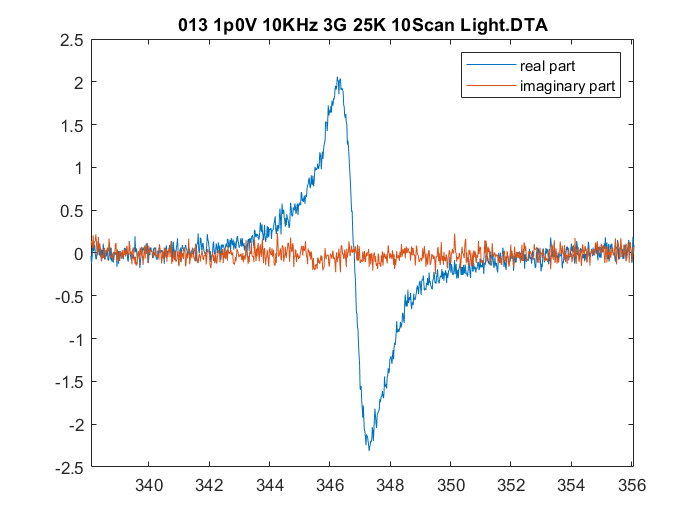

[data.spcFinalComplex, data.phase] = correctPhase(data.blc);
data.spcFinal = real(data.spcFinalComplex);

figure()
plot(data.B, real(data.spcFinalComplex))
hold on
plot(data.B, imag(data.spcFinalComplex))
xlim([min(data.B) max(data.B)])
legend('real part', 'imaginary part')
title(data.title)

## Fit 001 25K reverse 1V

Dangling Bond:

Sys0.S = 1/2;
Sys0.g = 2.00491;
Sys0.lw = [0.086 1.46];

Vary0.g = 0.001;
Vary0.lw = [0.1 1.8];

% Db2
Sys1.S = 1/2;
Sys1.g = 2.0087;
Sys1.lw = [0.11 3];
Sys1.weight = 1;

Vary1.g = 0.001;
Vary1.lw = [0.1 1.8];
Vary1.weight = 1;

FitOpt.Method = 'simplex fcn';
FitOpt.maxTime = 0.5;

Exp.mwFreq = ((9.7402 + 9.7403)/2 + (9.7406 + 9.7406)/2)/2; % GHz
Exp.Range = [min(data.B) max(data.B)];

% esfit('pepper', data.spcFinal, ...
%     Sys0, Vary0, Exp, [], FitOpt);
% esfit('pepper', data.spcFinal, ... 
%     {Sys0, Sys1}, {Vary0, Vary1}, Exp, [], FitOpt);
[fit.bestVal, fit.spc] = esfit('pepper', data.spcFinal, ...
   {Sys0, Sys1}, {Vary0, Vary1}, Exp, [], FitOpt);

-- esfit ------------------------------------------------
Simulation function:      pepper
Problem size:             1 spectra, 2 components, 7 parameters
Minimization method:      Nelder/Mead simplex
Residuals computed from:  data as is
Scaling mode:             lsq0
---------------------------------------------------------
initial simplex...
    1:  1.17863e-01  1.00000e-01  initial simplex
    2:  1.17863e-01  1.00000e-01  reflection
    3:  1.17863e-01  1.00000e-01  reflection
    4:  1.17863e-01  1.00000e-01  reflection
    5:  1.05364e-01  1.99000e-01  expansion
    6:  1.05364e-01  1.99000e-01  reflection
    7:  1.05364e-01  1.99000e-01  reflection
    8:  1.05364e-01  1.99000e-01  reflection
    9:  1.05364e-01  1.99000e-01  reflection
   10:  1.05364e-01  1.80342e-01  reflection
   11:  1.00505e-01  1.37807e-01  reflection
   12:  8.31673e-02  2.17805e-01  expansion
   13:  8.31673e-02  2.17805e-01  reflection
   14:  8.31673e-02  2.17805e-01  reflection
   15:  8.31673e-02  

## Nice looking plots

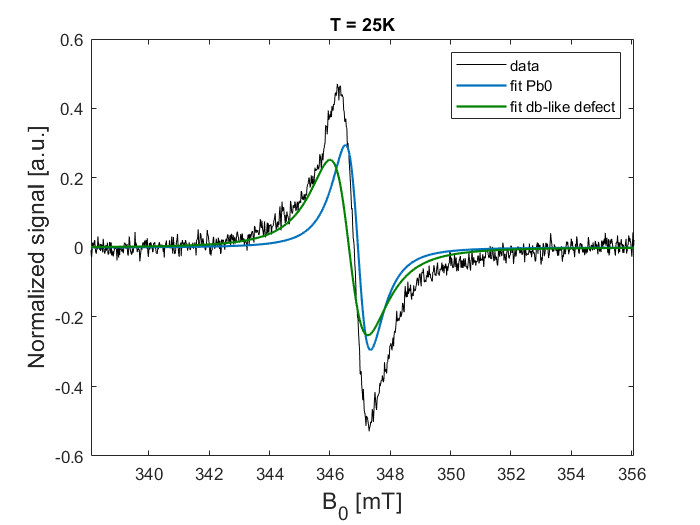

fit.yfitPb0 = pepper(fit.bestVal{1,1}, Exp);
fit.yfitDb2 = pepper(fit.bestVal{1,2}, Exp);

normFactor = 1/(max(fit.yfitPb0 + fit.yfitDb2) - ...
    min(fit.yfitPb0 + fit.yfitDb2));
fit.yfitPb0 = normFactor * fit.yfitPb0;
fit.yfitDb2 = normFactor * fit.yfitDb2;

figure()
plot(data.B, ...
    data.spcFinal/(max(data.spcFinal) - min(data.spcFinal)), 'k');
hold on
plot(data.B, fit.yfitPb0, 'Linewidth', 1.3, 'color', [0, 0.4470, 0.7410])
plot(data.B, fit.yfitDb2, 'Linewidth', 1.3, 'color', [0, 0.5, 0]);
title('T = 25K')

legend('data', 'fit Pb0', 'fit db-like defect')
xlabel('B_0 [mT]', 'FontSize', 14)
ylabel('Normalized signal [a.u.]', 'FontSize', 14)
xlim(Exp.Range)

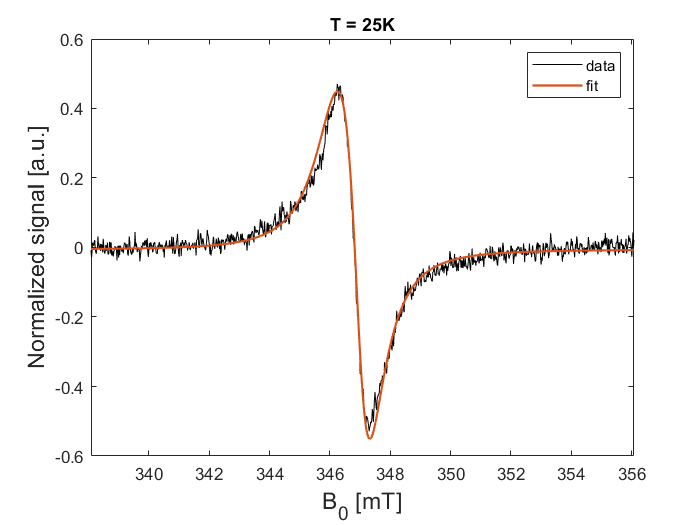


figure()
plot(data.B, ...
    data.spcFinal/(max(data.spcFinal) - min(data.spcFinal)), 'k');
hold on
plot(data.B, fit.spc/(max(fit.spc) - min(fit.spc)), ...
    'Linewidth', 1.3, 'color', '#D95319')
legend('data', 'fit')
xlabel('B_0 [mT]', 'FontSize', 14)
ylabel('Normalized signal [a.u.]', 'FontSize', 14)
xlim(Exp.Range)
title('T = 25K')

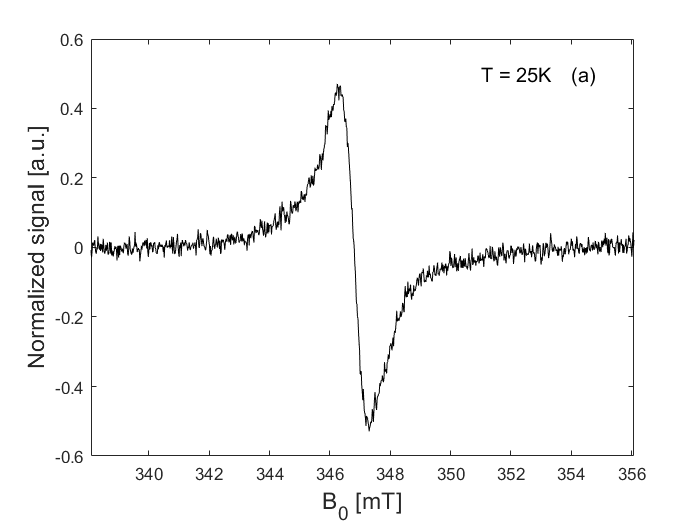


figure()
plot(data.B, ...
    data.spcFinal/(max(data.spcFinal) - min(data.spcFinal)), 'k');
xlabel('B_0 [mT]', 'FontSize', 14)
ylabel('Normalized signal [a.u.]', 'FontSize', 14)
xlim(Exp.Range)
text(354, .5, '(a)', 'FontSize', 12)
text(351, .5, 'T = 25K', 'FontSize', 12)